**P.43**

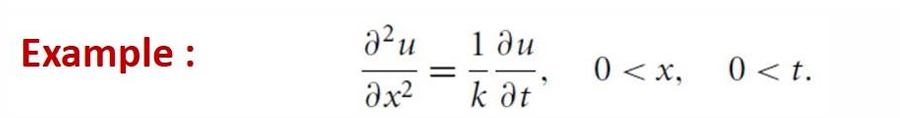

**Separation part**

clear
clf
clc
syms x t u(x,t) L D h
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;
syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0);
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

syms b_n ustruct(x,t,n);
expT(t,lambda) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,lambda) = subs(X(x,lambda),[lambda,sym('C2')],[lambda, b_n]);
ustruct(x,t) = collect(sinX(x,lambda)*expT(t,lambda),["sin" "exp"])

$$ustruct(x, t) = b_{n}\,\sin\left(\lambda \,x\right)\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

**Fourier integral part**

syms x t f(x) pi
L = inf; assume(t > 0 & x > 0)
D = 1

D = 1

ft0 = subs(ustruct(x,0),sym(["b_n" "L" "lambda"]),[1 L lambda])

$$ft0 = \sin\left(\lambda \,x\right)$$

b_n = (2/pi)*int(ft0*f,x,[0 L])

$$b\_n = \frac{2\,\int_{0}^{\infty }\sin\left(\lambda \,x\right)\,f\left(x\right)\mathrm{d}x}{\pi }$$

Heatstruct = int(ustruct,lambda,[0 L],'Hold',true)

$$Heatstruct(x, t) = \int_{0}^{\infty }b_{n}\,\sin\left(\lambda \,x\right)\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\mathrm{d}\lambda$$